cfgVHT = wlanVHTConfig('ChannelBandwidth', 'CBW20');
y = wlanLLTF(cfgVHT);
size(y)

ans =    160     1


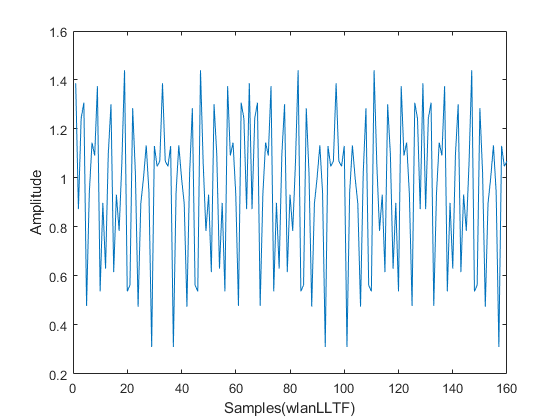

plot(abs(y))
xlabel('Samples(wlanLLTF)')
ylabel('Amplitude')

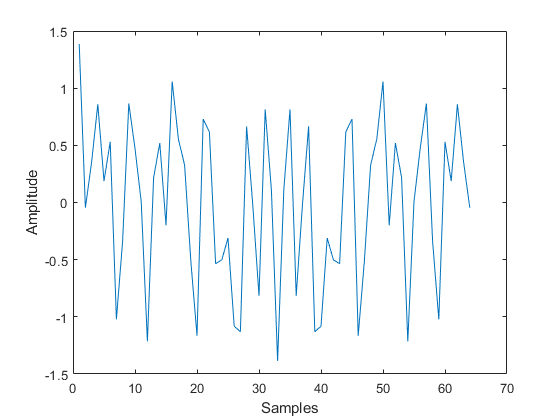


seqLong = [1;1;-1;-1;1;1;-1;1;-1;1;1;1;1;1;1;
            -1;-1;1;1;-1;1;-1;1;1;1;1;0;1;-1;-1;1;
            1;-1;1;-1;1;-1;-1;-1;-1;-1;1;1;-1;-1;1;-1;
            1;-1;1;1;1;1];
           
LTFpriorIFFT = [zeros(6,1);seqLong;zeros(5,1)];

k = -32:1:31;
k =  k'; 
% k(27) = [];
LTFifft = zeros(64,1);
for nn = 1:64       
        yy = LTFpriorIFFT .* exp(j*2*pi*k*(nn-1)/64);
        LTFifft(nn) = (1/sqrt(52)) * sum(yy) ;
end

% plot(abs(y(33:96)))
% xlabel('Samples')
% ylabel('Amplitude')

plot(real(LTFifft));
xlabel('Samples')
ylabel('Amplitude')

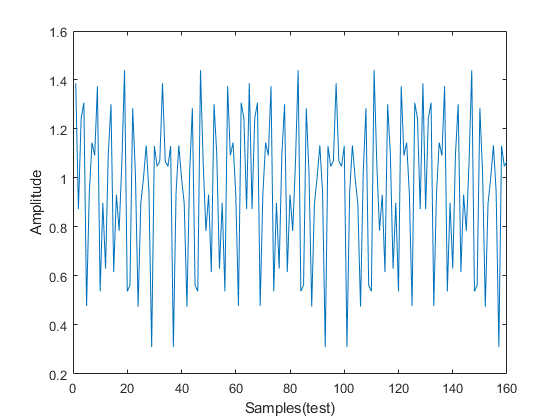



LTFifft_double = [LTFifft;LTFifft];
LTFifft_full = [LTFifft_double(97:128);LTFifft_double];

plot(abs(LTFifft_full))
xlabel('Samples(test)')
ylabel('Amplitude')

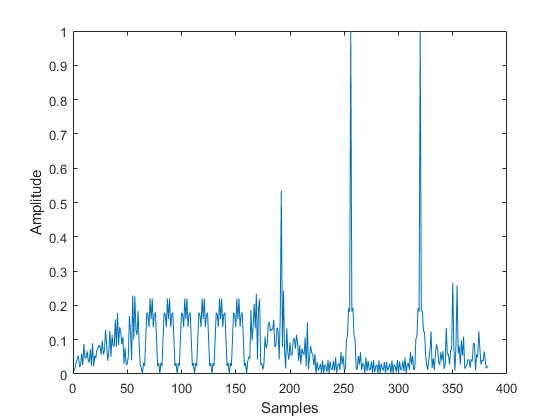


preamble = [STFifft_full;LTFifft_full];
% PREAMBLEcorr = zeros(160,1);
% STFcorr_append = [preamble;zeros(63,1)];
% for ss = 1:1:160
%     PREAMBLEcorr(ss) = sum(STFcorr_append(ss:64+ss-1).*STFifft);
% end
PREAMBLEcorr = xcorr(preamble,LTFifft);
plot(abs(PREAMBLEcorr(257:end))/max(abs(PREAMBLEcorr)));
xlabel('Samples')
ylabel('Amplitude')